# **Κεφάλαιο 2: Πολυστρωματικά δίκτυα perceptrons**

*Τα παραδείγματα και οι ασκήσεις που περιλαμβάνονται στο παρόν σημειωματάριο, βρίσκονται στο βιβλίο: Theodoridis S., Pikrakis A., Koutroumbas K., Cavouras D., Εισαγωγή στην Αναγνώριση Προτύπων με MATLAB, Εκδόσεις Πασχαλίδης, 2011*

## Πολυστρωματικά δίκτυα perceptrons

### Παράδειγμα 1

Έστω ένα διδιάστατο πρόβλημα ταξινόμησης δύο κλάσεων. Τα σημεία της πρώτης (δεύτερης κλάσης), αναπαρίστανται με $+1(-1)$ και προέρχονται από μία από τρεις (τέσσερις) ισοπίθανες Gaussian κατανομές, μέσης τιμής $[-5, 5]^T, [5, -5]^T, [10,0]^T, ([-5,-5]^T, [0,0]^T, [5,5]^T, [15,-5]^T) $. Το μητρώο συνδιασποράς κάθε κατανομής είναι ίσο με $\sigma^2I$ όπου $\sigma^2=1$ και $I$ είναι ο ταυτοτικός πίνακας $2\times 2$.

1. Δημιουργήστε και σχεδιάστε ένα σύνολο δεδομένων $X_1$ (σύνολο εκπαίδευσης) που περιέχει $60$ σημεία της κλάσης $+1$ ( $20$ από κάθε κατανομή) και $80$ σημεία της κλάσης $-1$ (και πάλι $20$ σημεία από κάθε κατανομή). Χρησιμοποιήστε την ίδια συνταγή για να παράγετε το σύνολο $X_2$ (σύνολο δοκιμής).

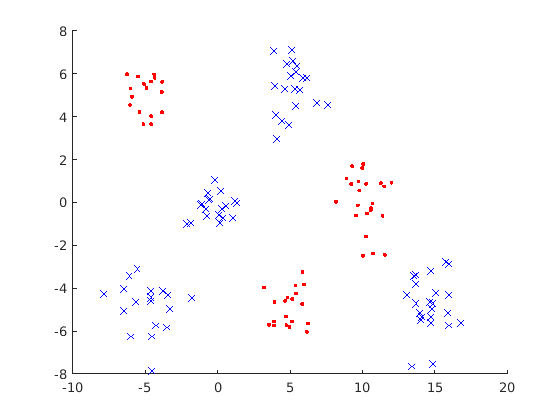

close('all');
clear;

randn('seed',0);
% 1. Generate data set X1 
l=2; %Dimensionality
m1=[-5 5; 5 -5; 10 0]'; % centroids
m2=[-5 -5; 0 0; 5 5; 15 -5]';
[l,c1]=size(m1); %no of gaussians per class
[l,c2]=size(m2);

P1=ones(1,c1)/c1; % weights of the mixture model
P2=ones(1,c2)/c2;
s=1; % variance

% Generate the training data from the first class
N1=60; %Number of first class data points
for i=1:c1
    S1(:,:,i)=s*eye(l);
end
sed=0; %Random generator seed
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Generate the training data from the second class
N2=80; %Number of second class data points
for i=1:c2
    S2(:,:,i)=s*eye(l);
end
sed=0; 
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);

% Form X1
X1=[class1_X  class2_X]; %Data vectors
y1=[ones(1,N1) -ones(1,N2)]; %Class labels
figure(1), hold on
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==-1),X1(2,y1==-1),'bx')


% Generate test set X2

% Data of the first class
sed=100; %Random generator seed. This time we set this value to 100
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Data of the second class
sed=100; %Random generator seed
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);

%Production of the unified data set
X2=[class1_X class2_X]; %Data vectors
y2=[ones(1,N1) -ones(1,N2)]; %Class labels

2. Με βάση το $X_1$, εκπαιδεύστε ένα νευρωνικό δίκτυο εμπρόσθιας διάδοσης, δύο στρωμάτων (Feed forward network - FNN), με δύο και τέσσερις κόμβους στο κρυφό επίπεδο. Όλοι οι κόμβοι του κρυφού επιπέδου χρησιμοποιούν την υπερβολική εφαπτομένη ως συνάρτηση ενεργοποίησης ($tanh(\cdot)$) ενώ ο κόμβος εξόδου χρησιμοποιεί τη γραμμική συνάρτηση ενεργοποίησης. Τρέξτε τον τυπικό αλγόριθμο οπίσθιας διάδοσης (BP) για $9000$ επαναλήψεις, με ρυθμό μάθησης $0.01$. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής (με βάση τα $X_1$ και $X_2$ αντίστοιχα) και σχεδιάστε τα σημεία εκπαίδευσης και τις περιοχές απόφασης που σχηματίζει το δίκτυο. Να γίνει επίσης η γραφική παράσταση του σφάλματος εκπαίδευσης ως προς το πλήθος των επαναλήψεων.

rand('seed',100) 
randn('seed',100)
iter=9000; %Number of iterations
code=1; %Code for the chosen training algorithm
k=5; %number of hidden layer nodes
lr=.01; %learning rate
par_vec=[lr 0 0 0 0];
%[net,tr]=NN_training(X1,y1,k,code,iter,par_vec);   %this uses the newff obsolete function
[net,tr]=NN_training_new(X1,y1,k,code,iter,par_vec); %this uses the new feedforwardnet function


% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)

pe_train = 0

pe_test=NN_evaluation(net,X2,y2)

pe_test = 0

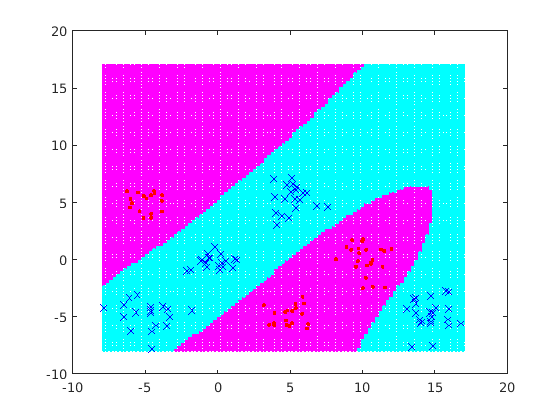


% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];
fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution
plot_NN_reg(net,bou,resolu,fig_num); % plot decision region
figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')

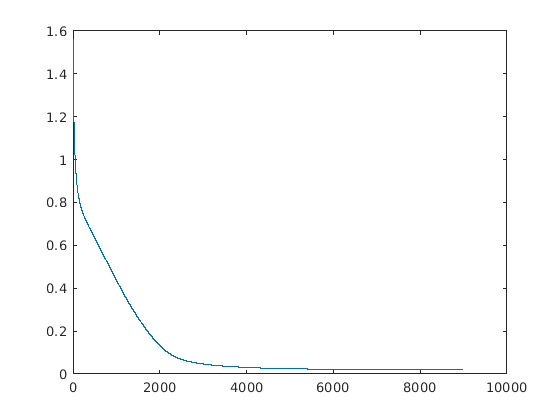


% Plot the training error versus the number of iterations

figure(3), plot(tr.perf)

3. Να επαναληφθεί το βήμα $2$, θέτοντας το ρυθμό μάθησης του BP αλγορίθμου ίσο με $0.0001$

rand('seed',100) 
randn('seed',100)

iter=9000; %Number of iterations
code=1; %Code for the chosen training algorithm
k=4; %number of hidden layer nodes
lr=.0001; %learning rate
par_vec=[lr 0 0 0 0]; %Parameter vector
%[net,tr]=NN_training(X1,y1,k,code,iter,par_vec);   %this uses the newff obsolete function
[net,tr]=NN_training_new(X1,y1,k,code,iter,par_vec); %this uses the new feedforwardnet function

% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)

pe_train = 0.5571

pe_test=NN_evaluation(net,X2,y2)

pe_test = 0.5500

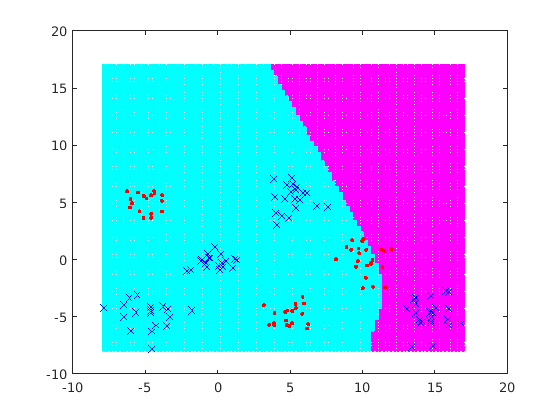


% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];
fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution
plot_NN_reg(net,bou,resolu,fig_num); % plot decision region
figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')

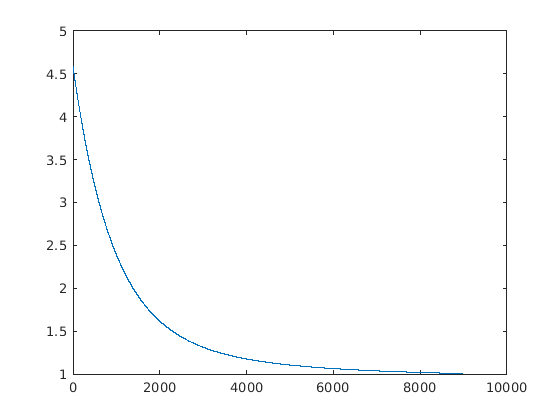


% Plot the training error versus the number of iterations
close(3) ; figure(3), plot(tr.perf)

4. Να επαναληφθεί το βήμα $2$, εφαρμόζοντας τον προσαρμοστικό BP αλγόριθμο, για $6000$ επαναλήψεις, με ρυθμό μάθησης $0.0001$, $r_i=1.05$, $r_d=0.7$ και $c=1.04$.

rand('seed',100) 
randn('seed',100)

iter=6000; %Number of iterations
code=3; %Code for the chosen training algorithm
k=10; %number of hidden layer nodes
lr=.01; %learning rate
par_vec=[lr 0 1.05 0.7 1.04]; %Parameter vector
%[net,tr]=NN_training(X1,y1,k,code,iter,par_vec);   %this uses the newff obsolete function
[net,tr]=NN_training_new(X1,y1,k,code,iter,par_vec); %this uses the new feedforwardnet function

% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)

pe_train = 0

pe_test=NN_evaluation(net,X2,y2)

pe_test = 0

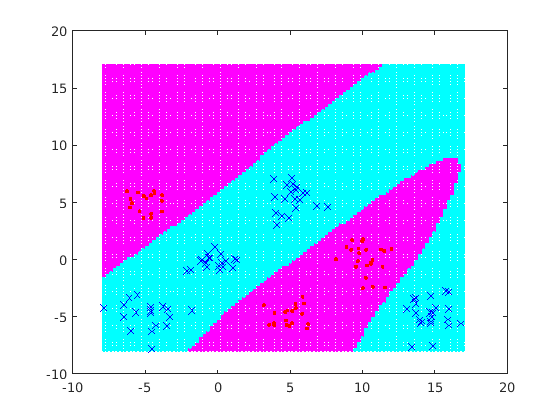


% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];
fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution
plot_NN_reg(net,bou,resolu,fig_num); % plot decision region
figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')

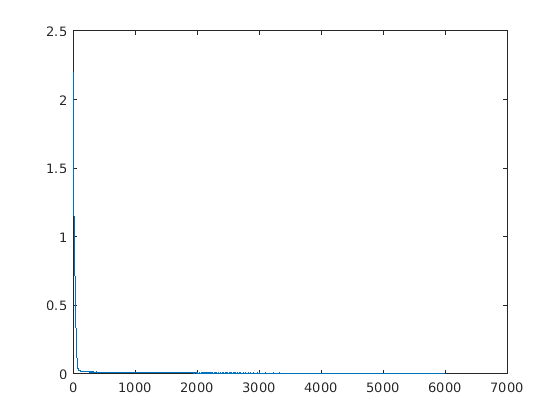


% Plot the training error versus the number of iterations
close(3) ; figure(3), plot(tr.perf)

5. Σχολιάστε τα αποτελέσματα των βημάτων $2,3$ και $4$.

### Άσκηση 1

Να επαναλάβετε το προηγούμενο παράδειγμα αλλά αυτή την φορά το μητρώο συνδιασποράς των Gaussian κατανομών να είναι ίσο με $\sigma^2I$ όπου $\sigma^2=4$ και $I$ είναι ο ταυτοτικός πίνακας $2\times 2$.

Σημειώστε ότι σε αυτή την περίπτωση, τα σημεία κάθε κλάσης έχουν μεγαλύτερη διασπορά και κατά συνέπεια οι κλάσεις δεν διαχωρίζονται με τόσο εμφανή τρόπο, όπως στο Παράδειγμα. Άρα αναμένουμε μια υποβάθμιση της απόδοσης των δικτύων που προκύπτουν. Τα ληφθέντα αποτελέσματα υποστηρίζουν τα συμπεράσματα του παραδείγματος με τη διαφορά ότι τώρα τα σφάλματα εκπαίδευσης και δοκιμής έχουν (ελαφρώς) αυξηθεί, συγκριτικά με εκείνα του προηγούμενου παραδείγματος.

### Παράδειγμα 2

Έστω δισδιάστατο πρόβλημα ταξινόμησης δύο κλάσεων. Τα σημεία της πρώτης (δεύτερης) κλάσης συμβολίζονται με $+1(-1)$ και πηγάζουν από τέσσερις (πέντε) ισοπίθανες Gaussian κατανομές με μέσες τιμές $[-10,0]^T,[0,-10]^T, [10,0]^T ([-10,-10]^T, [0,0]^T, [10,-10]^T, [-10,10]^T, [10,10]^T)$.  Το μητρώο συνδιασποράς κάθε κατανομής είναι ίσο με $\sigma^2I$ όπου $\sigma^2=4$ και $I$ είναι ο ταυτοτικός πίνακας $2\times 2$.

1. Δημιουργήστε και σχεδιάστε ένα σύνολο δεδομένων $X_1$ (σύνολο εκπαίδευσης) που περιέχει $80$ σημεία της κλάσης $+1$ ( $20$ από κάθε κατανομή) και $100$ σημεία της κλάσης $-1$ (και πάλι $20$ σημεία από κάθε κατανομή). Χρησιμοποιήστε την ίδια συνταγή για να παράγετε το σύνολο $X_2$ (σύνολο δοκιμής).

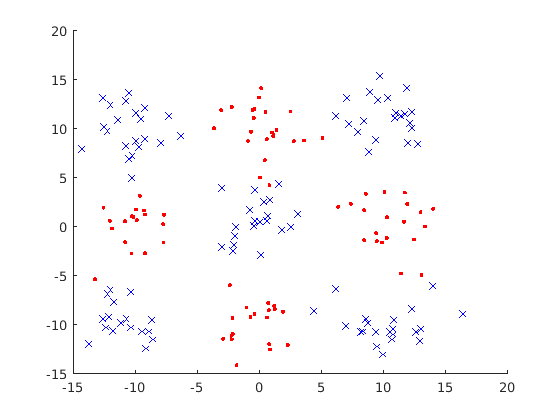

close('all');
clear;

randn('seed',0);
% 1. Generate the training data set (X1)
l=2; %Dimensionality
m1=[-10 0; 0 -10; 10 0; 0 10]'; % centroids of the first class
m2=[-10 -10; 0 0; 10 -10; -10 10;10 10]'; % centroids of the second class 
[l,c1]=size(m1); 
[l,c2]=size(m2);

P1=ones(1,c1)/c1;
P2=ones(1,c2)/c2;

% Generate data for the first class of the training set
N1=80; % Approximately 20 for each one of the four clusters
s=4;
for i=1:c1
    S1(:,:,i)=s*eye(l);
end
sed=0; %Random generator seed
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Generate data for the second class of X1
N2=100; % Approximately 20 for each one of the four clusters
for i=1:c2
    S2(:,:,i)=s*eye(l);
end
sed=0; %Random generator seed
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);

% Merge the data of the two classes to form the training set
X1=[class1_X  class2_X]; 
y1=[ones(1,N1) -ones(1,N2)]; 
figure(1), hold on
figure(1), plot(X1(1,y1==1),X1(2,y1==1),'r.',X1(1,y1==-1),X1(2,y1==-1),'bx')

% 1. Generate test set (X2)
% Generate data for the first class of X2
sed=100; 
[class1_X,class1_y]=mixt_model(m1,S1,P1,N1,sed);

% Generate data for the second class of X2
sed=100; 
[class2_X,class2_y]=mixt_model(m2,S2,P2,N2,sed);


% Form X2
X2=[class1_X  class2_X]; 
y2=[ones(1,N1) -ones(1,N2)]; 

2. Με βάση το $X_1$, εκπαιδεύστε ένα νευρωνικό δίκτυο εμπρόσθιας διάδοσης, δύο στρωμάτων (Feed forward network - FNN), με τρεις, τέσσερις και δέκα κόμβους στο κρυφό επίπεδο. Όλοι οι κόμβοι του κρυφού επιπέδου χρησιμοποιούν την υπερβολική εφαπτομένη ως συνάρτηση ενεργοποίησης (tanh) ενώ ο κόμβος εξόδου χρησιμοποιεί τη γραμμική συνάρτηση ενεργοποίησης. Χρησιμοποιήστε τον προσαρμοστικό BP αλγόριθμο για $10000$ επαναλήψεις και ρυθμό μάθησης $0.01$ και τις τιμές του προηγούμενου παραδείγματος για τις υπόλοιπες παραμέτρους του αλγορίθμου. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής (με βάση τα $X_1$ και $X_2$ αντίστοιχα) και σχεδιάστε τα σημεία δεδομένων και τις περιοχές απόφασης που σχηματίζει το δίκτυο. Να εξαχθούν συμπεράσματα.

iter=1000; % Number of iterations, substitute with 500, 1000, 2000, 3000, 4000, 5000, 10000
code=3; % Code for the chosen training algorithm
k=5; % number of hidden layer nodes
lr=.01; % learning rate
par_vec=[lr 0 1.05 0.7 1.04]; % Parameter vector
%[net,tr]=NN_training(X1,y1,k,code,iter,par_vec);   %this uses the newff obsolete function
[net,tr]=NN_training_new(X1,y1,k,code,iter,par_vec); %this uses the new feedforwardnet function

% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)
pe_test=NN_evaluation(net,X2,y2)

% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];
fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution
plot_NN_reg(net,bou,resolu,fig_num); % plot decision region

          See help for NEWFF to update calls to the new argument list.
 


figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')

pe_train = 0.1611

pe_test = 0.1389

% Plot the training error versus the number of iterations
 
 figure(3), plot(tr.perf)

3. Σχεδιάστε ένα FNN δύο επιπέδων με $10$ κόμβους στο κρυφό επίπεδο και χρησιμοποιήστε τον προσαρμοστικό BP αλγόριθμο για να το εκπαιδεύσετε, βασιζόμενοι στο $X_1$. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής για τις περιπτώσεις $300,400,1000,2000,3000,4000,5000,10000$ επαναλήψεων. Να τεθεί η παράμετρος μάθησης ίση με $0.01$, ενώ για τις υπόλοιπες παραμέτρους του αλγορίθμου χρησιμοποιήστε τις τιμές του προηγούμενου παραδείγματος. Να εξαχθούν συμπεράσματα.

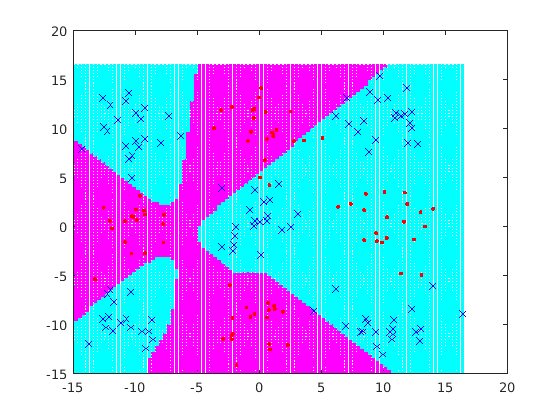

iter=10000; % Number of iterations, substitute with 500, 1000, 2000, 3000, 4000, 5000, 10000
code=3; % Code for the chosen training algorithm
k=10; % number of hidden layer nodes
lr=.01; % learning rate
par_vec=[lr 0 1.05 0.7 1.04]; % Parameter vector
%[net,tr]=NN_training(X1,y1,k,code,iter,par_vec);   %this uses the newff obsolete function
[net,tr]=NN_training_new(X1,y1,k,code,iter,par_vec); %this uses the new feedforwardnet function

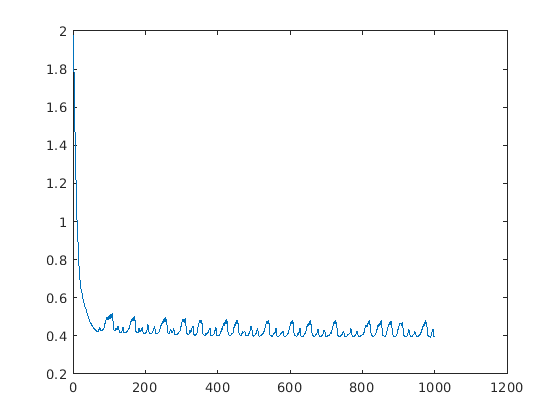


% Compute the training and the test errors
pe_train=NN_evaluation(net,X1,y1)
pe_test=NN_evaluation(net,X2,y2)


% Plot the data points as well as the decision regions of the FNN
maxi=max(max([X1'; X2']));
mini=min(min([X1'; X2']));
bou=[mini maxi];
fig_num=2; % figure handle
resolu=(bou(2)-bou(1))/100; % figure resolution
plot_NN_reg(net,bou,resolu,fig_num); % plot decision region
figure(fig_num), hold on % plot training set
figure(fig_num), plot(X1(1,y1==1),X1(2,y1==1),'r.', X1(1,y1==-1),X1(2,y1==-1),'bx')

% Plot the training error versus the number of iterations

pe_train = 0.0278

pe_test = 0.0444

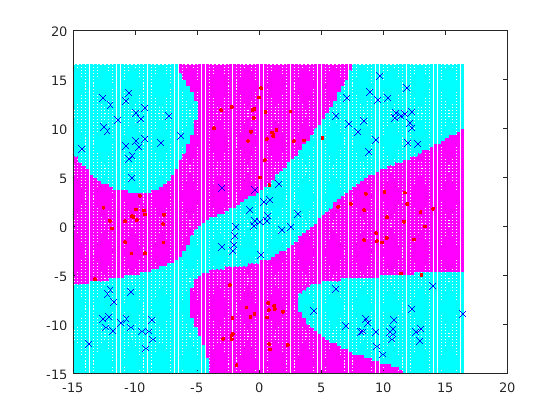

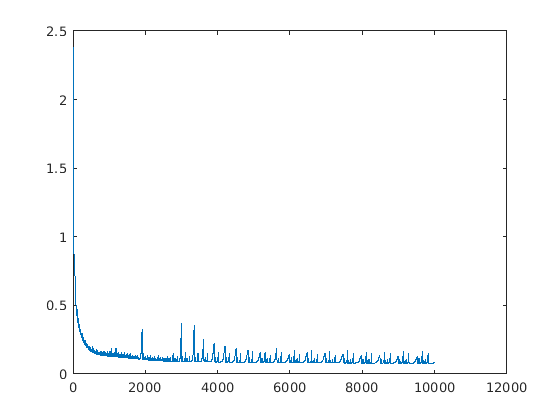

close (3) ; figure(3), plot(tr.perf)

### Άσκηση 2

Έστω δισδιάστατο πρόβλημα ταξινόμησης δύο κλάσεων. Τα σημεία της πρώτης (δεύτερης) κλάσης συμβολίζονται με $+1(-1)$ και πηγάζουν από οκτώ ισοπίθανες Gaussian κατανομές με μέσες τιμές $[-10,0]^T,[0,-10]^T, [10,0]^T, [-10,20]^T, [0,0]^T, [10,20]^T, [20,10]^T, [20,-10]^T ([-10,-10]^T,[0,0]^T,[10,-10]^T,[-10,10]^T,[10,10]^T,[20,20]^T,[20,0]^T,[0,20]^T)$.  Το μητρώο συνδιασποράς κάθε κατανομής είναι ίσο με $\sigma^2I$ όπου $\sigma^2=1$ και $I$ είναι ο ταυτοτικός πίνακας $2\times 2$.

- Δημιουργήστε και σχεδιάστε ένα σύνολο δεδομένων $X_1$ (σύνολο εκπαίδευσης) που περιέχει $160$ σημεία της κλάσης $+1$ ( $20$ από κάθε κατανομή) και $160$ σημεία της κλάσης $-1$ (και πάλι $20$ σημεία από κάθε κατανομή). Χρησιμοποιήστε την ίδια συνταγή για να παράγετε το σύνολο $X_2$ (σύνολο δοκιμής).

- Τρέξτε τον προσαρμοστικό  BP αλγόριθμο με ρυθμό μάθησης $0.01$ για $10000$ επαναλήψεις, προκειμένου να εκπαιδεύσετε ένα σύνολο από FNN δύο επιπέδων με $7,8,10,14,16,20,32,40$ κόμβους στο κρυφό επίπεδο (οι τιμές των υπόλοιπων παραμέτρων του προσαρμοστικού BP αλγορίθμου επιλέγονται όπως στο παράδειγμα 1.

- Να επαναληφθεί το βήμα 2 για $\sigma^2=2,3,4$ και να εξαχθούν συμπεράσματα. 

Παρατηρήστε ότι πρόκειται για ακόμα πιο σύνθετο πρόβλημα συγκριτικά με τα προηγούμενα και ο ελάχιστος απαιτούμενος αριθμός κόμβων στο κρυφό επίπεδο είναι υψηλότερος από τον απαιτούμενο αριθμό κόμβων στα προηγούμενα παραδείγματα. Σημειώστε επίσης ότι για το FNN με τους $16$ κόμβους στο κρυφό επίπεδο και για $\sigma^2=1$ και $4$, δεν επιτυγχάνεται ικανοποιητική λύση μολονότι το δίκτυο είναι κατά βάση ικανό να μάθει το πρόβλημα ταξινόμησης. Αυτό μπορεί να είναι συνέπεια του γεγονότος ότι το τοπίο της συνάρτησης κόστους $J(w)$ είναι τέτοιο ώστε αποτρέπει τον αλγόριθμο από το να συγκλίνει σε μια καλή λύση. Δηλαδή ο αλγόριθμος μπορεί να είναι παγιδευμένος σε τοπικό ελάχιστο της συνάρτησης κόστους που δεν ανταποκρίνεται σε μια ικανοποιητική λύση του προβλήματος ταξινόμησης που εξετάζουμε.

- Με βάση το $X_1$, εκπαιδεύστε ένα νευρωνικό δίκτυο εμπρόσθιας διάδοσης, δύο στρωμάτων (Feed forward network - FNN), με τρεις, τέσσερις και δέκα κόμβουςστο κρυφό επίπεδο. Όλοι οι κόμβοι του κρυφού επιπέδου χρησιμοποιούν την υπερβολική εφαπτομένη ως συνάρτηση ενεργοποίησης (tanh) ενώ ο κόμβος εξόδου χρησιμοποιεί τη γραμμική συνάρτηση ενεργοποίησης. Χρησιμοποιήστε τον προσαρμοστικό BP αλγόριθμο για $10000$ επαναλήψεις και ρυθμό μάθηση $0.01$ και τις τιμές του προηγούμενου παραδείγματος για τις υπόλοιπες παραμέτρους του αλγορίθμου. Υπολογίστε το σφάλμα εκπαίδευσης και δοκιμής (με βάση τα $X_1$ και $X_2$ αντίστοιχα) και σχεδιάστε τα σημεία δεδομένων και τις περιοχές απόφασης που σχηματίζει το δίκτυο. Να εξαχθούν συμπεράσματα.